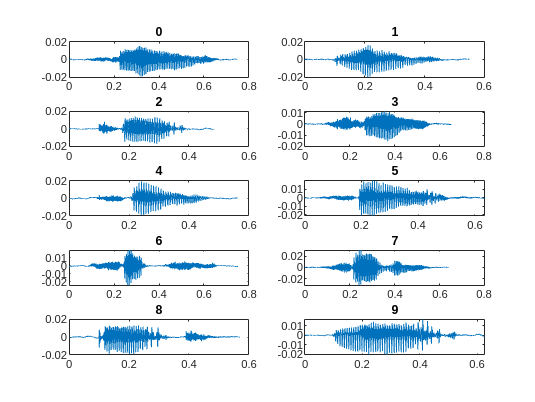

%cd Samples
clear;
for i = 0:9
    [y, Fs] = audioread(sprintf("%d_01_%d.wav", i, 0));
    
    Ts = 1 / Fs;
    [rows, cols] = size(y);
    t = 0:rows - 1;
    t = t .* Ts;

    subplot(5, 2, i + 1);
    plot(t, y');
    label = sprintf("%d", i);
    title(label);
end